clear
syms Rl R Ron Rd
syms L C_out
syms il vc vg vd
syms u v
A_1=[-(Rl+Ron)/L 0;0 -1/R/C_out]

$$A\_1 = \left(\begin{array}{cc} -\frac{\mathrm{Rl}+\mathrm{Ron}}{L} & 0\\ 0 & -\frac{1}{C_{\mathrm{out}}\,R} \end{array}\right)$$

A_2=[-(Rl+Rd)/L -1/L;1/C_out -1/R/C_out]

$$A\_2 = \left(\begin{array}{cc} -\frac{\mathrm{Rd}+\mathrm{Rl}}{L} & -\frac{1}{L}\\ \frac{1}{C_{\mathrm{out}}} & -\frac{1}{C_{\mathrm{out}}\,R} \end{array}\right)$$


B_1=[1/L 0;0 0]

$$B\_1 = \left(\begin{array}{cc} \frac{1}{L} & 0\\ 0 & 0 \end{array}\right)$$

B_2=[1/L -1/L;0 0]

$$B\_2 = \left(\begin{array}{cc} \frac{1}{L} & -\frac{1}{L}\\ 0 & 0 \end{array}\right)$$


x=[il;vc]

$$x = \left(\begin{array}{c} \mathrm{il}\\ \mathrm{vc} \end{array}\right)$$

v_f=[vg;vd]

$$v\_f = \left(\begin{array}{c} \mathrm{vg}\\ \mathrm{vd} \end{array}\right)$$

syms x1 x2
f_x=A_2*x+B_2*v_f

$$f\_x = \left(\begin{array}{c} \frac{\mathrm{vg}}{L}-\frac{\mathrm{vd}}{L}-\frac{\mathrm{vc}}{L}-\frac{\mathrm{il}\,\left(\mathrm{Rd}+\mathrm{Rl}\right)}{L}\\ \frac{\mathrm{il}}{C_{\mathrm{out}}}-\frac{\mathrm{vc}}{C_{\mathrm{out}}\,R} \end{array}\right)$$

fx=subs(f_x,[il vc],[x1 x2])

$$fx = \left(\begin{array}{c} \frac{\mathrm{vg}}{L}-\frac{\mathrm{vd}}{L}-\frac{x_{2}}{L}-\frac{x_{1}\,\left(\mathrm{Rd}+\mathrm{Rl}\right)}{L}\\ \frac{x_{1}}{C_{\mathrm{out}}}-\frac{x_{2}}{C_{\mathrm{out}}\,R} \end{array}\right)$$

g_x=(A_1-A_2)*x-(B_1-B_2)*v_f

$$g\_x = \left(\begin{array}{c} \mathrm{il}\,\left(\frac{\mathrm{Rd}+\mathrm{Rl}}{L}-\frac{\mathrm{Rl}+\mathrm{Ron}}{L}\right)+\frac{\mathrm{vc}}{L}-\frac{\mathrm{vd}}{L}\\ -\frac{\mathrm{il}}{C_{\mathrm{out}}} \end{array}\right)$$


x_dot=f_x+g_x*u

$$x\_dot = \left(\begin{array}{c} u\,\left(\mathrm{il}\,\left(\frac{\mathrm{Rd}+\mathrm{Rl}}{L}-\frac{\mathrm{Rl}+\mathrm{Ron}}{L}\right)+\frac{\mathrm{vc}}{L}-\frac{\mathrm{vd}}{L}\right)-\frac{\mathrm{vc}}{L}-\frac{\mathrm{vd}}{L}+\frac{\mathrm{vg}}{L}-\frac{\mathrm{il}\,\left(\mathrm{Rd}+\mathrm{Rl}\right)}{L}\\ \frac{\mathrm{il}}{C_{\mathrm{out}}}-\frac{\mathrm{vc}}{C_{\mathrm{out}}\,R}-\frac{\mathrm{il}\,u}{C_{\mathrm{out}}} \end{array}\right)$$


x_dot=subs(x_dot,il,x1)

$$x\_dot = \left(\begin{array}{c} \frac{\mathrm{vg}}{L}-\frac{\mathrm{vd}}{L}-\frac{\mathrm{vc}}{L}+u\,\left(x_{1}\,\left(\frac{\mathrm{Rd}+\mathrm{Rl}}{L}-\frac{\mathrm{Rl}+\mathrm{Ron}}{L}\right)+\frac{\mathrm{vc}}{L}-\frac{\mathrm{vd}}{L}\right)-\frac{x_{1}\,\left(\mathrm{Rd}+\mathrm{Rl}\right)}{L}\\ \frac{x_{1}}{C_{\mathrm{out}}}-\frac{\mathrm{vc}}{C_{\mathrm{out}}\,R}-\frac{u\,x_{1}}{C_{\mathrm{out}}} \end{array}\right)$$

x_dot=subs(x_dot,vc,x2)

$$x\_dot = \left(\begin{array}{c} \frac{\mathrm{vg}}{L}-\frac{\mathrm{vd}}{L}-\frac{x_{2}}{L}+u\,\left(x_{1}\,\left(\frac{\mathrm{Rd}+\mathrm{Rl}}{L}-\frac{\mathrm{Rl}+\mathrm{Ron}}{L}\right)-\frac{\mathrm{vd}}{L}+\frac{x_{2}}{L}\right)-\frac{x_{1}\,\left(\mathrm{Rd}+\mathrm{Rl}\right)}{L}\\ \frac{x_{1}}{C_{\mathrm{out}}}-\frac{x_{2}}{C_{\mathrm{out}}\,R}-\frac{u\,x_{1}}{C_{\mathrm{out}}} \end{array}\right)$$

x_dot=simplify(x_dot)

$$x\_dot = \left(\begin{array}{c} -\frac{\mathrm{vd}-\mathrm{vg}+x_{2}+\mathrm{Rd}\,x_{1}+\mathrm{Rl}\,x_{1}+u\,\mathrm{vd}-u\,x_{2}-\mathrm{Rd}\,u\,x_{1}+\mathrm{Ron}\,u\,x_{1}}{L}\\ -\frac{x_{2}-R\,x_{1}+R\,u\,x_{1}}{C_{\mathrm{out}}\,R} \end{array}\right)$$

x_dot=collect(x_dot,[u x1])

$$x\_dot = \left(\begin{array}{c} \frac{\mathrm{Rd}-\mathrm{Ron}}{L}\,u\,x_{1}+\left(-\frac{\mathrm{vd}-x_{2}}{L}\right)\,u+\left(-\frac{\mathrm{Rd}+\mathrm{Rl}}{L}\right)\,x_{1}-\frac{\mathrm{vd}-\mathrm{vg}+x_{2}}{L}\\ \left(-\frac{1}{C_{\mathrm{out}}}\right)\,u\,x_{1}+\frac{x_{1}}{C_{\mathrm{out}}}-\frac{x_{2}}{C_{\mathrm{out}}\,R} \end{array}\right)$$


x1_dot=simplify(x_dot(1))

$$x1\_dot = \frac{\mathrm{Rd}-\mathrm{Ron}}{L}\,u\,x_{1}+\left(-\frac{\mathrm{vd}-x_{2}}{L}\right)\,u+\left(-\frac{\mathrm{Rd}+\mathrm{Rl}}{L}\right)\,x_{1}-\frac{\mathrm{vd}-\mathrm{vg}+x_{2}}{L}$$


y=x1;
ydot=x_dot(2);


g=(ydot - subs(ydot,u,0))/u

$$g = -\frac{x_{1}}{C_{\mathrm{out}}}$$

f=ydot-u*g

$$f = \frac{x_{1}}{C_{\mathrm{out}}}-\frac{x_{2}}{C_{\mathrm{out}}\,R}$$


upr=1/g*(-f+v)

$$upr = -\frac{C_{\mathrm{out}}\,\left(v-\frac{x_{1}}{C_{\mathrm{out}}}+\frac{x_{2}}{C_{\mathrm{out}}\,R}\right)}{x_{1}}$$


%racunanje funkcije upravljanja upr_Block
C_out=500e-6;
R=15

R = 15

upr = eval(upr);
upr_f = matlabFunction(upr)

upr_f = function_handle with value:
    @(v,x1,x2)-(v./2.0e+3-x1+x2./1.5e+1)./x1


f =eval(f);
f_f = matlabFunction(f)

f_f = function_handle with value:
    @(x1,x2)x1.*2.0e+3-x2.*(4.0e+2./3.0)



g =eval(g);
g_f = matlabFunction(g)

g_f = function_handle with value:
    @(x1)x1.*-2.0e+3



z1 = eval(ydot)

$$z1 = 2000\,x_{1}-\frac{400\,x_{2}}{3}-2000\,u\,x_{1}$$

z1_f = matlabFunction(z1)

z1_f = function_handle with value:
    @(u,x1,x2)x1.*2.0e+3-x2.*(4.0e+2./3.0)-u.*x1.*2.0e+3


L=250e-6;   % H
vd=0.7;     % V
Rd=0.5;     % Ohm
Rl=0.2;     % Ohm
C=500e-6;   % F
Ron=0.3;      % Ohm
vg=12

vg = 12

x2e=24;%Dozvoljene vrednosti x1(300,338.9) 
x10=10;
x20=4;
ref_V=24;
sum=0;
poremecaj=1;
promena_ref=0;
sigma=0.01;
%jednacine ya racunanje stacionarnih vrednosti
syms x2 x1 u
eq=[u*(x1*((Rd + Rl)/L - (Rl + Ron)/L) + x2/L - vd/L) - x2/L - vd/L + vg/L - (x1*(Rd + Rl))/L...
    ,x1/C-x2/R/C+(-x1)/C*u];
rez=solve(eq,[x1 u]);
x1e=rez.x1;
x1e=subs(x1e,x2,x2e);
x1e=eval(x1e)

x1e =     4.7016
   15.8584


ue=rez.u;
ue=subs(ue,x2,x2e);
ue=eval(ue)%u(0,0.05)

ue =     0.6597
    0.8991


x10=1.5;




%Generisanje PID (ne moze samo PI jer bi imao gresku stacionarnog stanja)
syms Kp Kd Ki s wf
PID=(Kd*wf*s^2+Kp*s+Ki)/(s^2+wf*s)

$$PID = \frac{\mathrm{Kd}\,\mathrm{wf}\,s^{2}+\mathrm{Kp}\,s+\mathrm{Ki}}{s^{2}+\mathrm{wf}\,s}$$

Ob=1/s

$$Ob = \frac{1}{s}$$

W=PID*Ob

$$W = \frac{\mathrm{Kd}\,\mathrm{wf}\,s^{2}+\mathrm{Kp}\,s+\mathrm{Ki}}{s\,\left(s^{2}+\mathrm{wf}\,s\right)}$$

g=simplify(W/(1+W))

$$g = \frac{\mathrm{Kd}\,\mathrm{wf}\,s^{2}+\mathrm{Kp}\,s+\mathrm{Ki}}{\mathrm{Ki}+\mathrm{Kp}\,s+s^{2}\,\mathrm{wf}+s^{3}+\mathrm{Kd}\,s^{2}\,\mathrm{wf}}$$

g=collect(g,s)

$$g = \frac{\left(\mathrm{Kd}\,\mathrm{wf}\right)\,s^{2}+\mathrm{Kp}\,s+\mathrm{Ki}}{s^{3}+\left(\mathrm{wf}+\mathrm{Kd}\,\mathrm{wf}\right)\,s^{2}+\mathrm{Kp}\,s+\mathrm{Ki}}$$

zel=(s+50)^3

$$zel = {\left(s+50\right)}^{3}$$

zel=collect(zel,s)

$$zel = s^{3}+150\,s^{2}+7500\,s+125000$$


Kp=7500

Kp = 7500

Ki=125000

Ki = 125000

pid=tf([Kp Ki],[1 0])

pid =
 
  7500 s + 125000
  ---------------
         s
 
Continuous-time transfer function.



obj=tf([0 1],[1 0 0])

obj =
 
   1
  ---
  s^2
 
Continuous-time transfer function.




w=pid*obj

w =
 
  7500 s + 125000
  ---------------
        s^3
 
Continuous-time transfer function.



f=minreal(ss(w/(1+w)))

3 states removed.

f =
 
  A = 
           x1      x2      x3
   x1       0  -117.2  -61.04
   x2      64       0       0
   x3       0      32       0
 
  B = 
       u1
   x1  16
   x2   0
   x3   0
 
  C = 
          x1     x2     x3
   y1      0  7.324  3.815
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



f=tf(f)

f =
 
             7500 s + 125000
  --------------------------------------
  s^3 - 3.908e-14 s^2 + 7500 s + 1.25e05
 
Continuous-time transfer function.



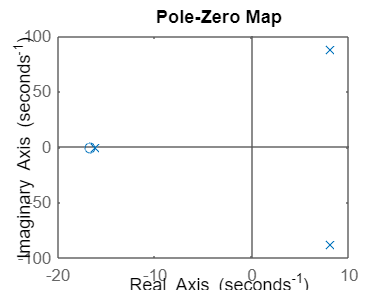

pzmap(f)

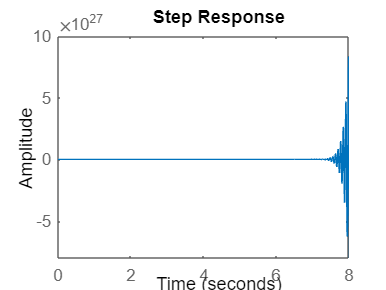

step(f)


Kd=50

Kd = 50


wf=100

wf = 100

wpref=wf*10;
dif=tf([Kd*wf],[1 wf])

dif =
 
   5000
  -------
  s + 100
 
Continuous-time transfer function.



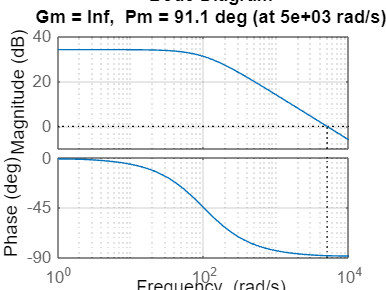

margin(dif)
grid on


pid=tf([Kd Kp Ki],[1 wf 0])

pid =
 
  50 s^2 + 7500 s + 125000
  ------------------------
        s^2 + 100 s
 
Continuous-time transfer function.



obj=tf([0 1],[1 0 ])

obj =
 
  1
  -
  s
 
Continuous-time transfer function.




w=pid*obj

w =
 
  50 s^2 + 7500 s + 125000
  ------------------------
       s^3 + 100 s^2
 
Continuous-time transfer function.



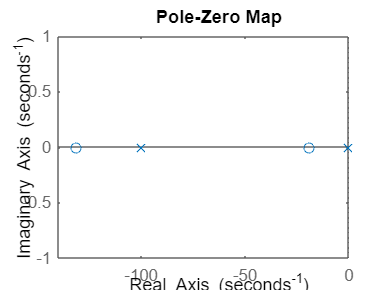

pzmap(w)

f=minreal(ss(w/(1+w)))

3 states removed.

f =
 
  A = 
           x1      x2      x3
   x1  -148.5  -51.53  -41.18
   x2     196   9.333   33.92
   x3  -42.23   29.01  -10.86
 
  B = 
           u1
   x1   11.14
   x2  -7.131
   x3   2.282
 
  C = 
          x1     x2     x3
   y1  7.513  5.774  3.269
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



f=tf(f)

f =
 
     50 s^2 + 7500 s + 1.25e05
  --------------------------------
  s^3 + 150 s^2 + 7500 s + 1.25e05
 
Continuous-time transfer function.



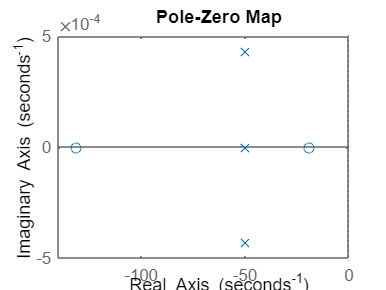

pzmap(f)

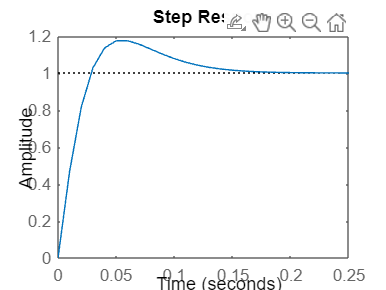

step(f)


piddis=c2d(pid,1/50e3)

piddis =
 
  50 z^2 - 99.85 z + 49.85
  ------------------------
   z^2 - 1.998 z + 0.998
 
Sample time: 2e-05 seconds
Discrete-time transfer function.

